addpath('Classes')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

# FSFB Controller with Feed-Forward - Tuning

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions

end 


%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 

%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;

end

plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated

if (~exist('FSFB_FF', 'var'))

    FSFB_FF = Lin_FSFB_Cntrl(Lnrzed_EOMs, plant_model, VDefs, 'FSFB FF Controller');

end

## Desired Trajectory in x and y

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide

%Rose curve specified by k
tot_period = 7 %this many seconds before the entire rose curve loops around

tot_period = 7

n = 4; %Selects a rose curve
d = 1; %Selects a rose curve
k = n/d; 
omega_sim = omega_rose(tot_period,n,d)

omega_sim = 0.8976

des_traj_sym_x(VDefs.t) = r_sim/2*(cos((k+1)*omega_sim*VDefs.t) + cos((k-1)*omega_sim*VDefs.t));
des_traj_sym_y(VDefs.t) = r_sim/2*(sin((k+1)*omega_sim*VDefs.t) - sin((k-1)*omega_sim*VDefs.t));

%Simple STAY AT THE ICs SETPOINT for tuning inner angular loops
% des_traj_sym_x(VDefs.t) = x_0(1) + 0*VDefs.t;
% des_traj_sym_y(VDefs.t) = x_0(5) + 0*VDefs.t;

%Go to some location on the plate
% des_traj_sym_x(VDefs.t) = -r_sim + 0*VDefs.t;
% des_traj_sym_y(VDefs.t) = -r_sim/2 + 0*VDefs.t;

%Square waveform
% des_traj_sym_x(VDefs.t) = r_sim*sign(sin(((VDefs.t))*omega_sim));
% des_traj_sym_y(VDefs.t) = r_sim*sign(cos(((VDefs.t))*omega_sim));

% d_x_s = sum(sub_exps_d_x_s);


figure
fplot(des_traj_sym_x, 'r--') 
xlim([0 tot_period]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

figure
fplot(des_traj_sym_y, 'r--') 
xlim([0 tot_period]); 
ylabel('y setpoint [m]')
xlabel('time [s]')

tplot = 0:0.01:tot_period;
setpoint_shape = double([des_traj_sym_x(tplot)',des_traj_sym_y(tplot)']);
figure
plot(setpoint_shape(:,1),setpoint_shape(:,2), 'r--')
xlabel('x setpoint [m]')
ylabel('y setpoint [m]')
axis equal



## Gain Matrices 

A1a = FSFB_FF.sys_mats.A1a;
A2a = FSFB_FF.sys_mats.A2a;

B1a = FSFB_FF.sys_mats.B1a;
B2a = FSFB_FF.sys_mats.B2a;

Q_e_ix = 1/15^2;
Q_e_x = 1/.001^2;
Q_e_xd = 1/.002^2; 
Q_b = 1/deg2rad(40)^2/.5; 
Q_bd = 1/omega_sim^2/3;


Q = [Q_e_ix 0 0 0 0; 
     0 Q_e_x 0 0 0;
     0 0 Q_e_xd 0 0;
     0 0 0 Q_b 0;
     0 0 0 0 Q_bd];

R = 1/(73/1000)^2/10; 

## Simulate the Feed-Forward Controller

K1 = lqr(double(A1a), double(B1a), Q,R)
K2 = lqr(double(A2a), double(B2a), Q,R)

%Specify initial conditions and compute initial outputs
x_0 = 0*[r_sim; 0; 0; 0; r_sim; 0; 0; 0];

%Specify simulation time
tspan = [0 tot_period*4];

%First order smoothing with time constant Tau
Tau = 0.5; 

FSFB_FF.Run_Sim(des_traj_sym_x, des_traj_sym_y, tspan, x_0,Tau, K1, K2);

simout_FF = FSFB_FF.sim_response

## Plot the Respose

%Plot the FF controller results
FF_fig = FSFB_FF.plot_results('FSFB w/ Feed-Forward');

## Animate Response

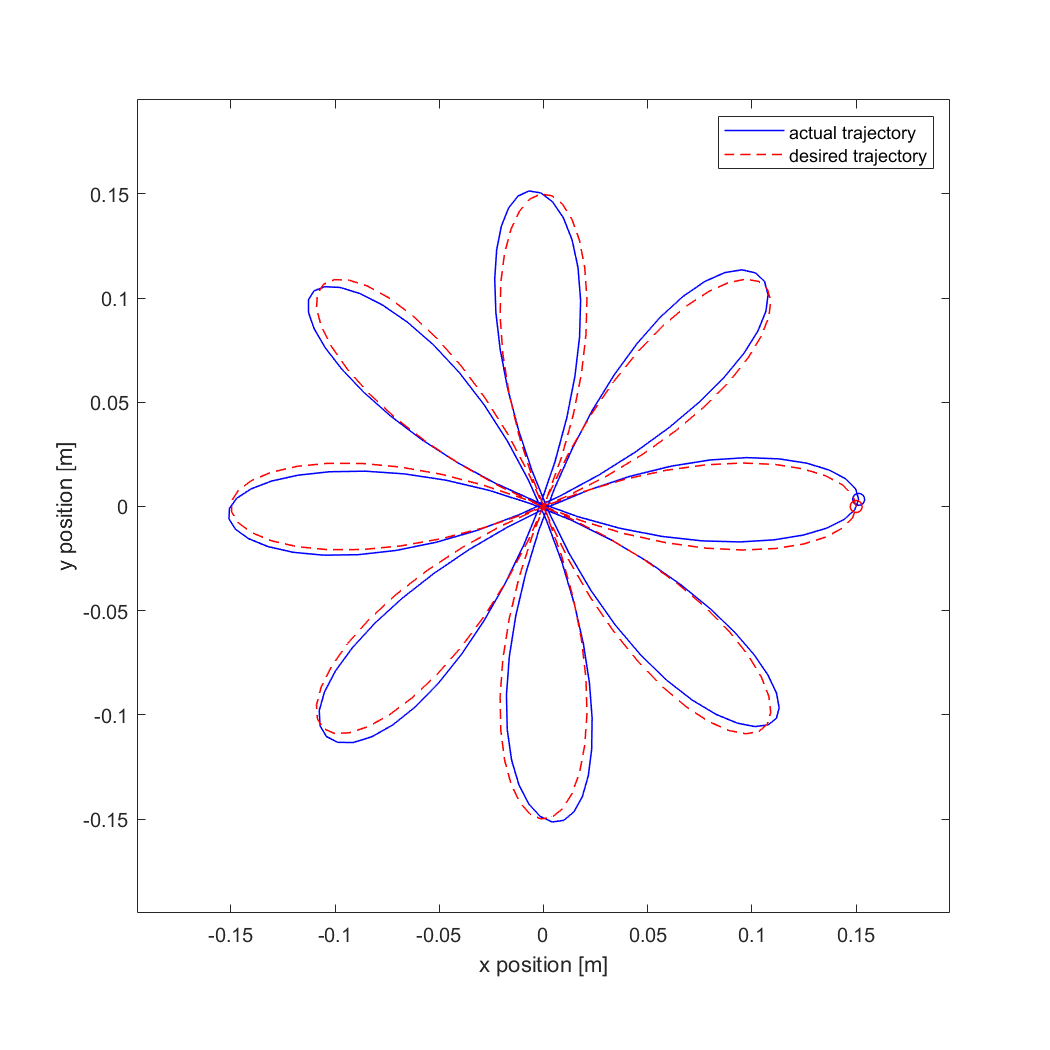

i_plot = simout_FF.tout>=2*tot_period & simout_FF.tout<=3*tot_period;
t_window = tot_period;
fps = 25;
Animate_Response(simout_FF.x(i_plot,1),simout_FF.x_s_vec(i_plot,1),...
     simout_FF.x(i_plot,5),simout_FF.y_s_vec(i_plot,1),simout_FF.tout(i_plot),fps,'LMSP_FF.gif', r_sim, t_window)

view_vec = [140 40];
Animate_Response_3D(simout_FF.x(i_plot,:),simout_FF.tout(i_plot),25,'LMSP_FF_3D.gif',VDefs, view_vec, setpoint_shape)